% SNR Measurement Script for Sound Localization Project
% Setup: 40cm, 60cm, 80cm, 100cm

fs = 44100;        % Sampling frequency (Hz)
duration = 5;      % Duration of each recording (seconds)
nBits = 16;        % Bit depth
nChannels = 1;     % Change to 4 if using your 4-mic array

distances = [30, 50, 80, 100]; 
snr_results = zeros(length(distances), 1);


%% 1. Record Noise Floor (Ambient Room Noise)
fprintf('--- STEP 1: Ambient Noise Recording ---\n');

--- STEP 1: Ambient Noise Recording ---


fprintf('Keep the room quiet. Recording for %d seconds...\n', duration);

Keep the room quiet. Recording for 5 seconds...



recNoise = audiorecorder(fs, nBits, nChannels);
recordblocking(recNoise, duration);
noiseData = getaudiodata(recNoise);
rms_noise = sqrt(mean(noiseData.^2));

fprintf('Noise Floor RMS: %.6f\n\n', rms_noise);

Noise Floor RMS: 0.001242




%% 2. Record Signal at Each Distance
fprintf('--- STEP 2: Signal Recordings ---\n');

--- STEP 2: Signal Recordings ---



for i = 1:length(distances)
    input(sprintf('Place source at %d cm and press Enter to record...', distances(i)));
    
    recSignal = audiorecorder(fs, nBits, nChannels);
    recordblocking(recSignal, duration);
    totalData = getaudiodata(recSignal);
    
    % Calculate RMS of Total (Signal + Noise)
    rms_total = sqrt(mean(totalData.^2));
    
    % Extract Pure Signal RMS: sqrt(RMS_total^2 - RMS_noise^2)
    % We use max() to prevent imaginary numbers if noise > total (rare)
    rms_signal = sqrt(max(0, rms_total^2 - rms_noise^2));
    
    % Calculate SNR in dB
    snr_results(i) = 20 * log10(rms_signal / rms_noise);
    
    fprintf('Distance: %d cm | SNR: %.2f dB\n', distances(i), snr_results(i));
end

Distance: 40 cm | SNR: 34.21 dB
Distance: 60 cm | SNR: 33.63 dB
Distance: 80 cm | SNR: 33.43 dB
Distance: 100 cm | SNR: 32.13 dB



%% 3. Display Results Table
T = table(distances', snr_results, 'VariableNames', {'Distance_cm', 'SNR_dB'});
disp('--- Final Results ---');

--- Final Results ---


disp(T);

    Distance_cm    SNR_dB
    ___________    ______

         30          0   
         50          0   
         80          0   
        100          0   



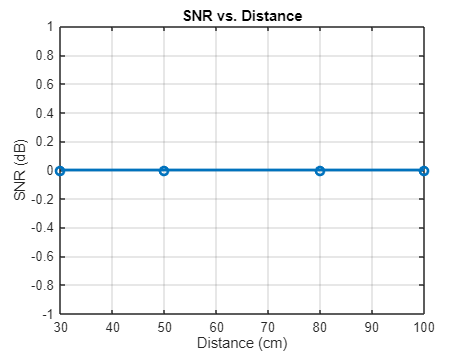


% Plotting the results
figure;
plot(distances, snr_results, '-o', 'LineWidth', 2);
grid on;
xlabel('Distance (cm)');
ylabel('SNR (dB)');
title('SNR vs. Distance');